Number of points ($N_p$ in lecture):

N  = 80;

...evenly spaced across the domain from 0 to 2:

nd = linspace(0,2,N)';

Attempt to interpolate $\sin \left(x\right)$:

f = @(x) sin(x);   % func, chosen to interp

Interpolation then is just simply a linear combination of each of the Lagrange basis 1 to N, times the value of our function, which we've put in an anonymous function `f`, at each of our nodes `nd`. So `nd` here is the locations from our linspace. 

Lag function definition (recall from lecture):

nn = elim(nd(1:N)',nd(1:N)',[1 3 2]);
Lag = @(x,nv) prod(bsxfun(@rdivide,bsxfun(@minus,x,nn(nv,:,:)),...
                   bsxfun(@minus,nd(nv),nn(nv,:,:))),3);
interp_f = @(x) f(nd')*Lag(x,1:N);

$f\left(x\right)=\sin \left(x\right)$ values @ certain points:

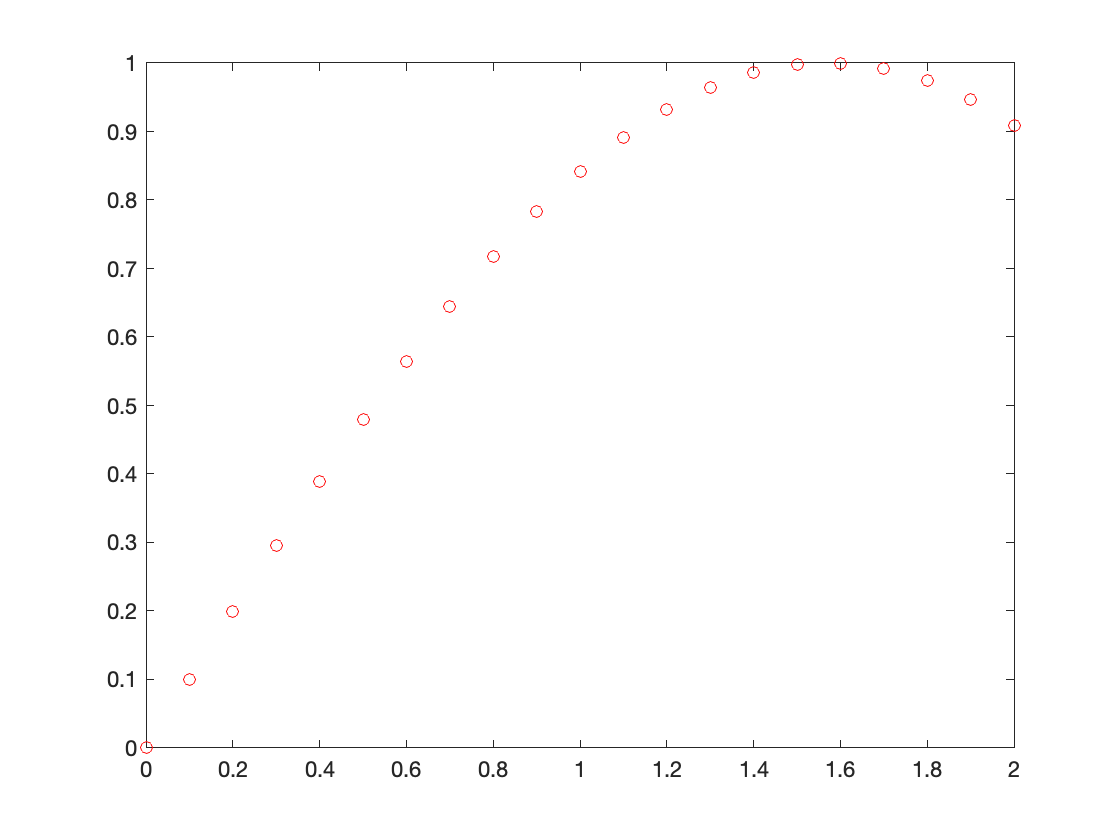

xx2 = 0:.1:2;
plot(xx2,f(xx2),'o','color',"red")
hold off

Exact & Approx ploted together

- Equispaced:

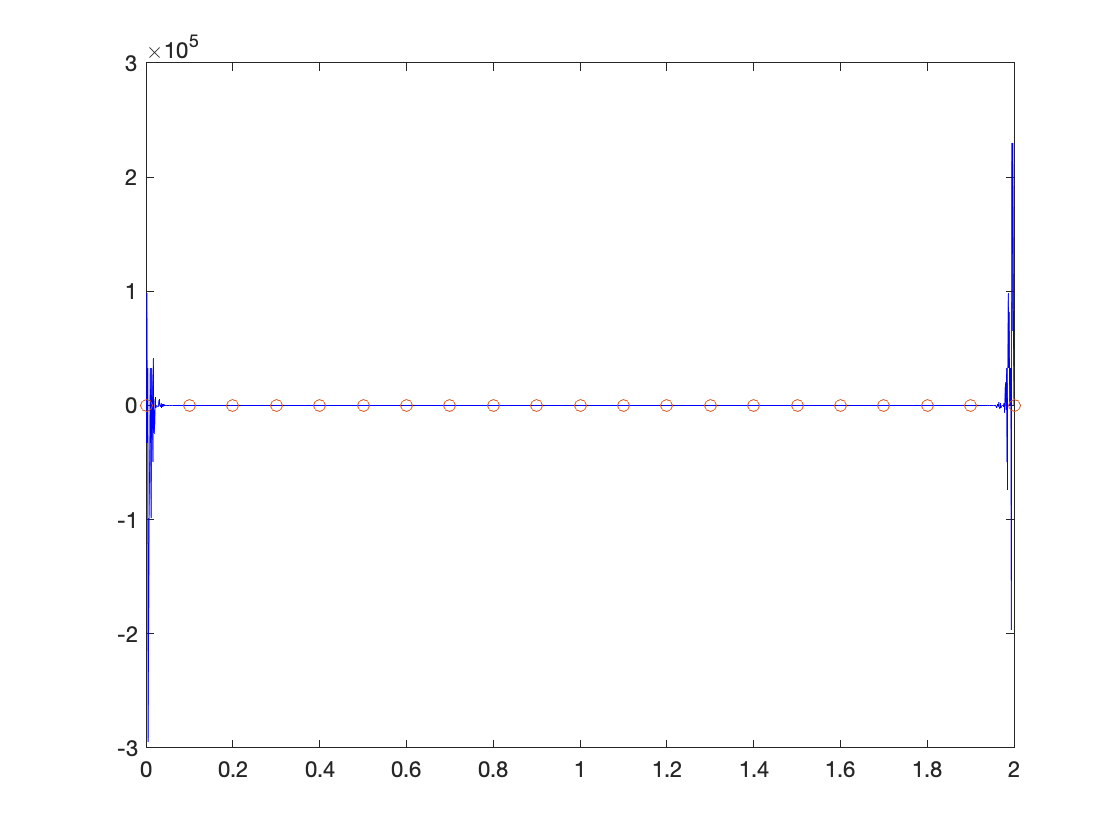

xx  = 0:.001:2;
plot(xx,interp_f(xx),'b')
hold on
plot(xx2,f(xx2),'o')
hold off

*Tip: try lower N values instead! What does the difference tell us?*

- Legendre roots:

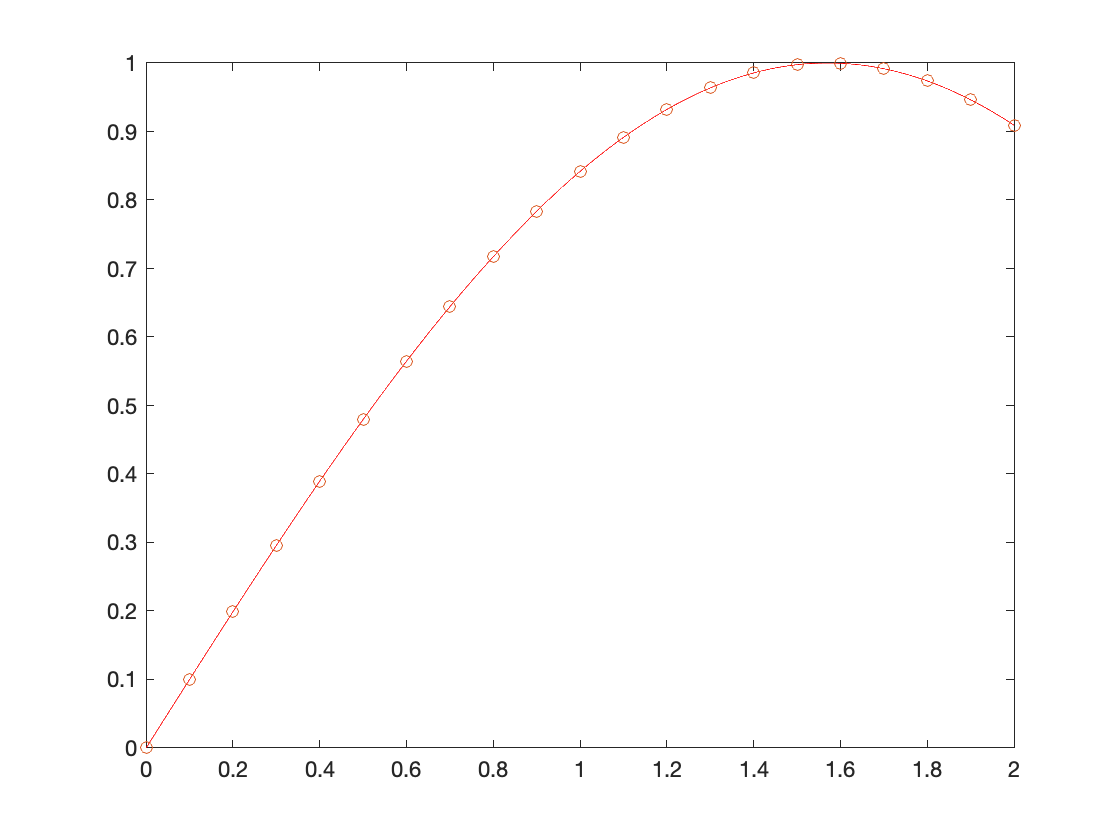

[Qx, Qw] =  GLquad(N);
Qx   = Qx+1;
nn2  = elim(Qx(1:N)',Qx(1:N)',[1 3 2]);
Lag2 = @(x,nv) prod(bsxfun(@rdivide,bsxfun(@minus,x,nn2(nv,:,:)),...
                    bsxfun(@minus,Qx(nv),nn2(nv,:,:))),3);
interp_f2 = @(x) f(Qx')*Lag2(x,1:N);
plot(xx,interp_f2(xx),'r')
hold on
plot(xx2,f(xx2),'o')